# Eigenfaces - Face Recognition with Linear Algebra

## Reading the Dataset

clear all; close all; clc; %#ok


The matrix $I$ will has the all images in one matrix

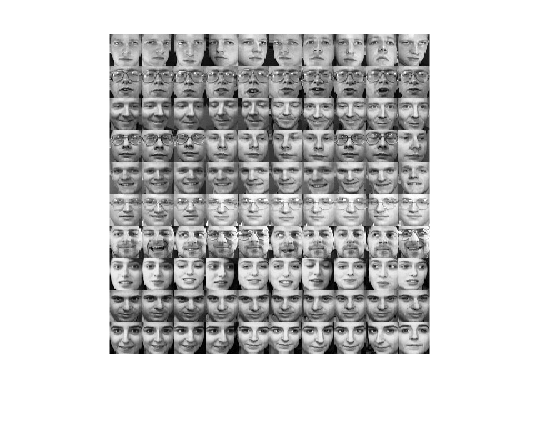

I = im2double(imread('faces.jpg'));
imshow(I)

In the cell array C, each row has images of one person

C = mat2cell(I,32*ones(10,1),32*ones(10,1)); 

To show the original dataset

imshow(I)

Now, to access 3rd image of the 2nd person we write: 

im = C{2,3};
size(im)

ans =     32    32


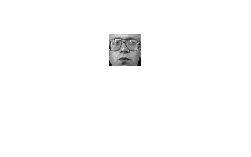

imshow(im)

Each image is 32x32 pixles.

## Preparation

Split the images to Trainning and testing:

Tr_img = C(1:10,1:8);
Ts_img = C(1:10,9:10); 


Reshape the images to have one matrix, with each column represent one image for one person:

Tr_img = reshape(cell2mat(reshape(Tr_img',1,[])),32*32,80);
Ts_img = reshape(cell2mat(reshape(Ts_img',1,[])),32*32,20);

Now, we start prepairing the training data for projection

M = mean(Tr_img,2); %The mean image of all the training data


Now, we centralize the training data by subtracting the mean:

A = Tr_img - M;

Just to take view on how the training data in terms of correlation:

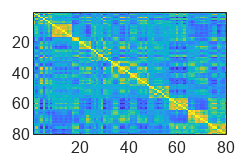

imagesc(corr(A))

## Singular Value Decomposition

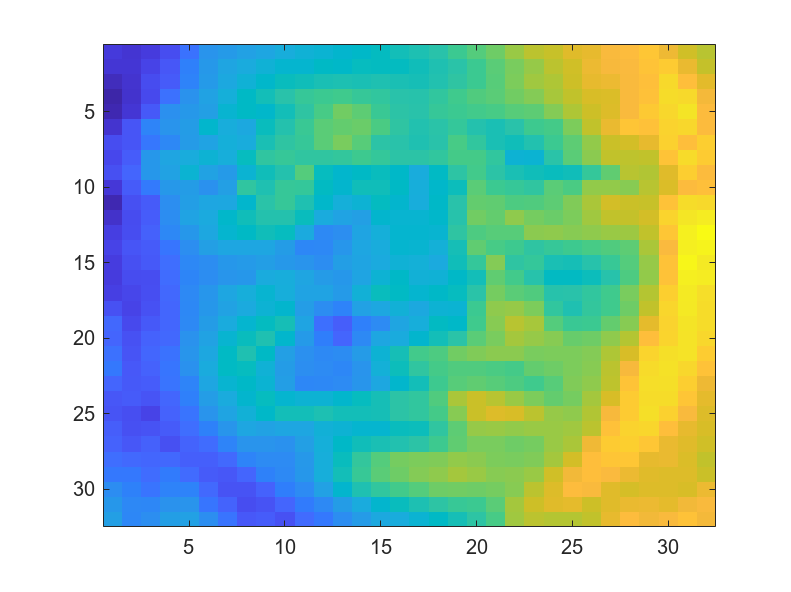

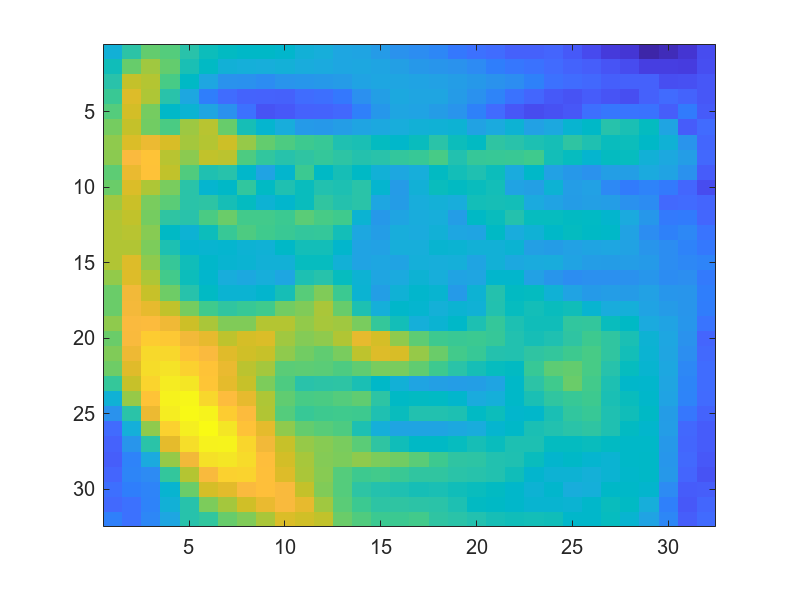

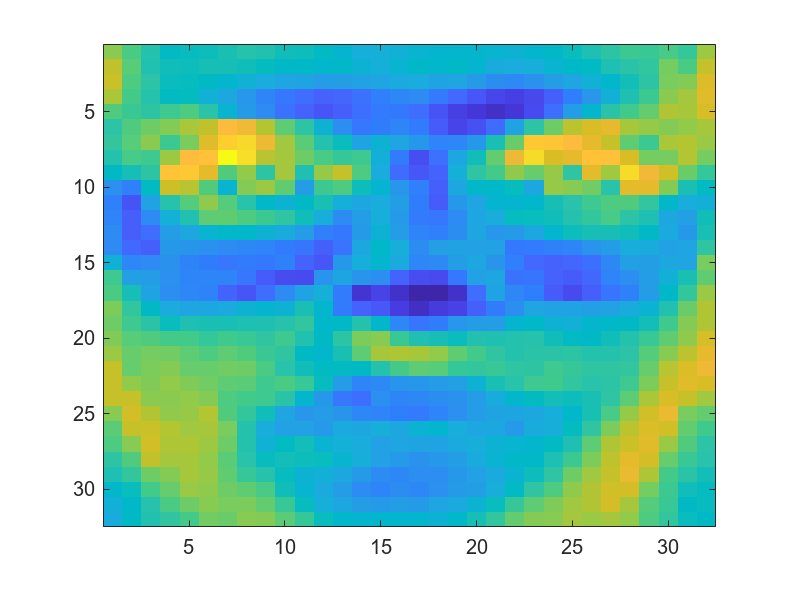

[U,S,V] = svd(A);

EigFaces = A * V;

%To show some of the eigenfaces
for i=1:3
    figure
    imagesc(reshape(EigFaces(:,i),32,32))
end

## Projection to the face space

Now, we find the images (training and testing) projection on the face space

imgProjection = EigFaces'*A;
testProjection = EigFaces'*bsxfun(@minus,Ts_img,M);

Now the test data and training data are projected to a space where it is easier to distinguish distances:

Distance = pdist2(testProjection',imgProjection');
[~,matchIndx] = min(Distance,[],2);


Now, we will show a few images from the test images (randomly selected) together with the closest image from the training data:

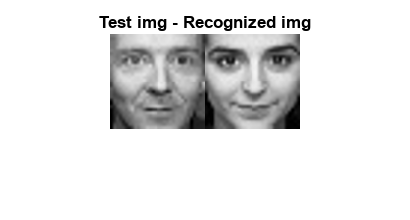

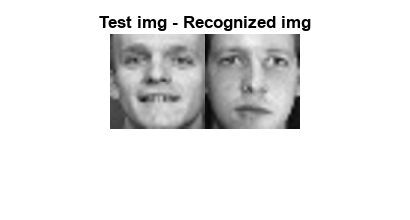

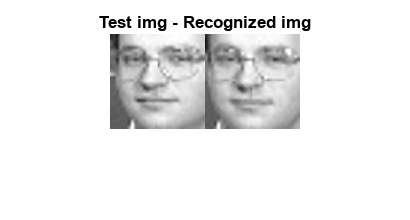

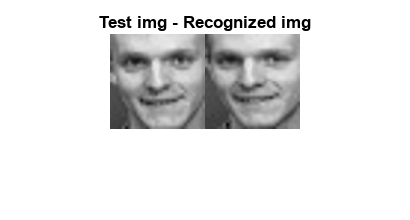

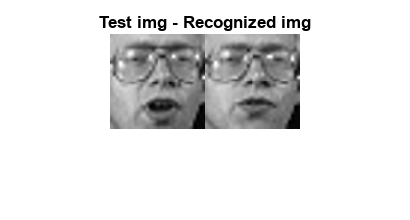

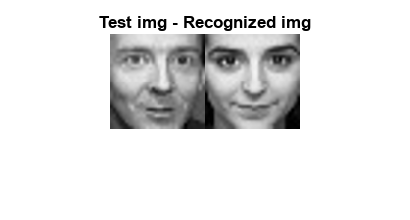

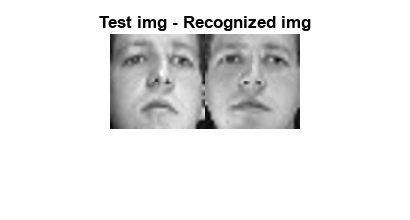

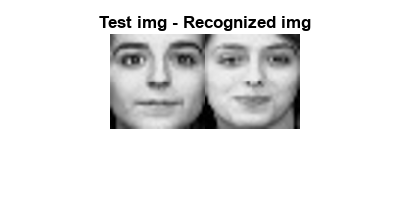

showIndx = randperm(20,10); 
%
% In the following Figure
% You will find in each subplot two images (left) is test image and (right) is the recognized image
for i=1:length(showIndx)
    figure
    imshow([imresize(reshape(Ts_img(:,showIndx(i)),32,32),3),...
    imresize(reshape(Tr_img(:,matchIndx(showIndx(i))),32,32),3)]);
    title('Test img - Recognized img')
end 